N = 20; % liczba wierszy
M = 20; % liczba kolumn

% Macierz A

A = speye(N * M);

for i = 2 : (N - 1)
    for j = 2 : (M - 1)        
        k  = i + (j - 1) * N;        
        A(k, k) = 4;
        A(k, k - 1) = -1;
        A(k, k + 1) = -1;
        A(k, k - M) = -1;
        A(k, k + M) = -1;        
    end
end

C = (2:2:N);

b = zeros(N * M, 1);

for i = C(end) / 2 : C(end) / 2 + 2   
    j = 1;
    k = i + (j - 1) * N;
    b(k) = 300; % temperatura z lewej strony
    j = M;
end

for i = 1 : N % pętla po numerze wiersza
    j = 1;
    j = M;
    k = i + (j - 1) * N;
    b(k) = 20; % temperatura z prawej strony
end

for j = 1 : M  % pętla po numerze kolumny
    i = 1;
    k = i + (j - 1) * N;    
    b(k) = 20; % temperatura u góry
    i = M;
    k = i + (j - 1) * N;    
    b(k) = 20; % temperatura u dołu
end

%A = sparse(A);

tic
T = A \ b;
toc

Elapsed time is 0.006459 seconds.


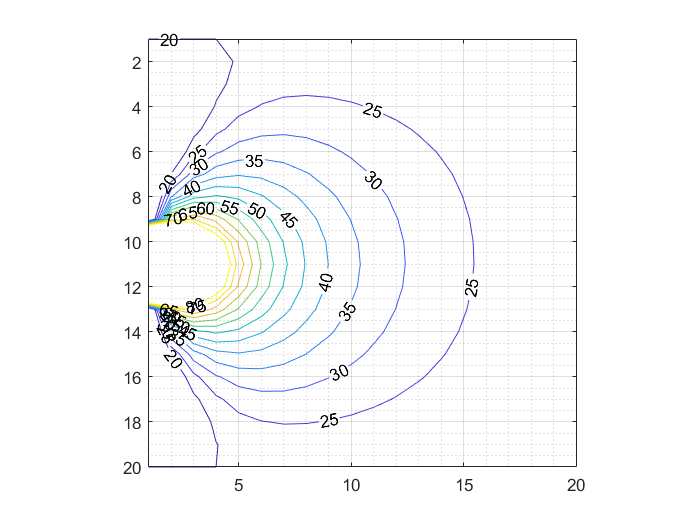


T = reshape(T, N, M);

contour(T,20:5:80, 'ShowText', 'on');
grid on;
grid minor;
axis ij;
axis equal;